# Adding biological constraints to a flux balance model

## Authors: Diana C. El Assal and Ronan M.T. Fleming,  Luxembourg Centre for Systems Biomedicine, University of Luxembourg, Luxembourg.

## Reviewers: 

Sylvain Arreckx, Laurent Heirendt, Ronan M.T. Fleming

## INTRODUCTION

A cell-type or organ-specific model can be converted into a condition-specific model, based on the imposition of experimentally derived constraints. By convention, the bounds set on reaction rates in a metabolic model range from -1000 to 1000 and from 0 to 1000 for reversible and irreversible reactions, respectively [1]. There are several types of constraints that can be imposed in a metabolic model, such as biomass maintenance requirements, environmental constraints, or maximal enzyme activities.  

In general, biomass constraints [2] are added as part of a biomass reaction. In some instances, however, a cell-type (e.g. neurons) does not divide, but is only required to turn over its biomass components. This tutorial is particularly relevant for such cases. Turnover rates are commonly expressed as half-lives (${t_{1/2}$) and represent the time required for half of the biomass precursor to be replaced [3]. 

Using the experimental literature, metabolite ${t_{1/2}$ were collected and converted into turnover rates ($\lambda$):


$$\text{(1)}\ \lambda=\frac{ln(2)}{t_{1/2}}\\
$$


We consider a biochemical network of  m  molecular species and  n  biochemical reactions. The biochemical network is mathematically represented by a stoichiometric matrix $S\in\mathcal{Z}^{m\times n}$.  After calculating $\lambda$, we integrate it into the steady-state equation:


$$\text{(2)}\ Sv=\frac{dx}{dt}\\$$


The steady-state flux vector $v
$ and the change in abundance over time ($\frac{dx}{dt}\\
$) share the same units, with  $x
$  being the abundance of the corresponding biomass precursor. Equation (2) can thus be re-written: 


$$
\text{(3)}\ Sv=\frac{dx}{dt}=\lambda x\\
$$


## PROCEDURE

Unless the model is already loaded into the workspace, ReconX needs to be loaded. 

clear model
if ~exist('modelOrig','var')
    filename='ReconX';
    directory='~/work/sbgCloud/programReconstruction/projects/recon2models/data/cobraTutorials';
    model = loadIdentifiedModel(filename,directory);
    model.csense(1:size(model.S,1),1)='E';
    modelOrig = model;
else
    model=modelOrig;
    model.csense(1:size(model.S,1),1)='E';
end

## CRITICAL STEP: Conversion of experimental fluxes (Timing: 1-2 weeks)

When constraining a model, it is crucial to impose correctly calculated or converted flux rates. It is recommended to first define the flux unit you wish to use. A common unit used for prokaryotic models is micromol per gramDryWeight per hour ($\mu mol/gDW/hr$). However, in the experimental literature, a wide range of units is provided. Therefore, after each conversion, it is strongly recommended to double check the calculations to avoid modelling artifacts. 

## **1. Environmental constraints**

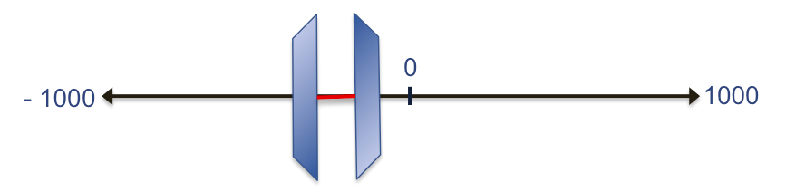

Examples of environmental constraints include the availability of glucose or oxygen to the model. Glucose consumption rate in the caudate-putamen of the conscious rat was found to range between -12.00 and -11.58  $\mu mol/gDW/hr$[4]. Therefore, set a constraint on the glucose exchange reaction in the model, as follows:

modelConstrained = model;
modelConstrained = changeRxnBounds(modelConstrained, 'EX_glc_D[e]', -12, 'l');

Optionally, to further constrain the model, an upper bound can also be imposed to force the model to take up between 11.58 and 12 units of glucose 

modelConstrained = changeRxnBounds(modelConstrained, 'EX_glc_D[e]', -11.58, 'u');

## **2. Internal enzymatic constraints **

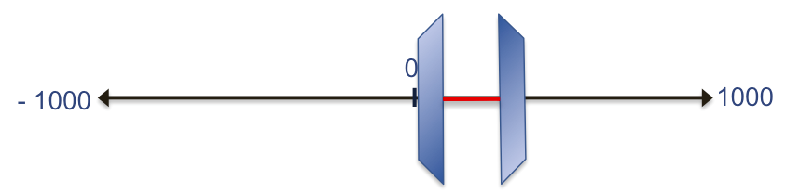

Using organ, tissue, or cell-type specific experimental literature, we can sometimes identify maximum enzyme activities (Vmax). Assuming that the fructose-bisphosphate aldolase reaction ([FBA](http://vmh.uni.lu/#reaction/FBA)) has a Vmax of 128 units in our specific cell type, we can then add this constraint on the corresponding internal reaction FBA, as an upper bound. This represents the maximal catalytic activity of the corresponding enzyme. 

modelConstrained = changeRxnBounds(modelConstrained, 'FBA', 128, 'u');

Optionally, if the reaction is reversible, the same constraint can be set as the lower bound, but with opposite signs.

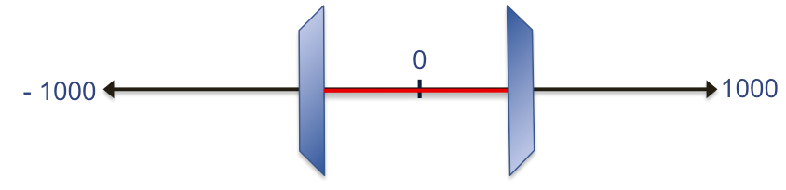

modelConstrained = changeRxnBounds(modelConstrained, 'FBA', -128, 'l');

## **3. Biomass constraints**

For dividing cell types, the generic human biomass reaction available in ReconX is formulated as follows:

printRxnFormula(modelConstrained, 'biomass_reaction');

biomass_reaction	20.6508 h2o[c] + 20.7045 atp[c] + 0.385872 glu_L[c] + 0.352607 asp_L[c] + 0.036117 gtp[c] + 0.505626 ala_L[c] + 0.279425 asn_L[c] + 0.046571 cys_L[c] + 0.325996 gln_L[c] + 0.538891 gly[c] + 0.392525 ser_L[c] + 0.31269 thr_L[c] + 0.592114 lys_L[c] + 0.35926 arg_L[c] + 0.153018 met_L[c] + 0.023315 pail_hs[c] + 0.039036 ctp[c] + 0.154463 pchol_hs[c] + 0.055374 pe_hs[c] + 0.020401 chsterol[c] + 0.002914 pglyc_hs[c] + 0.011658 clpn_hs[c] + 0.009898 dgtp[n] + 0.009442 dctp[n] + 0.013183 datp[n] + 0.053446 utp[c] + 0.013091 dttp[n] + 0.275194 g6p[c] + 0.126406 his_L[c] + 0.159671 tyr_L[c] + 0.286078 ile_L[c] + 0.545544 leu_L[c] + 0.013306 trp_L[c] + 0.259466 phe_L[c] + 0.412484 pro_L[c] + 0.005829 ps_hs[c] + 0.017486 sphmyln_hs[c] + 0.352607 val_L[c] 	->	20.6508 h[c] + 20.6508 adp[c] + 20.6508 pi[c] 


**biomass_reaction**

20.6508 h2o[c] + 20.7045 atp[c] + 0.38587 glu_L[c] + 0.35261 asp_L[c] + 0.036117 gtp[c] + 0.50563 ala_L[c] + 0.27942 asn_L[c] + 0.046571 cys_L[c] + 0.326 gln_L[c] + 0.53889 gly[c] + 0.39253 ser_L[c] + 0.31269 thr_L[c] + 0.59211 lys_L[c] + 0.35926 arg_L[c] + 0.15302 met_L[c] + 0.023315 pail_hs[c] + 0.039036 ctp[c] + 0.15446 pchol_hs[c] + 0.055374 pe_hs[c] + 0.020401 chsterol[c] + 0.002914 pglyc_hs[c] + 0.011658 clpn_hs[c] + 0.009898 dgtp[n] + 0.009442 dctp[n] + 0.013183 datp[n] + 0.053446 utp[c] + 0.013091 dttp[n] + 0.27519 g6p[c] + 0.12641 his_L[c] + 0.15967 tyr_L[c] + 0.28608 ile_L[c] + 0.54554 leu_L[c] + 0.013306 trp_L[c] + 0.25947 phe_L[c] + 0.41248 pro_L[c] + 0.005829 ps_hs[c] + 0.017486 sphmyln_hs[c] + 0.35261 val_L[c]  -> 20.6508 h[c] + 20.6508 adp[c] + 20.6508 pi[c] 

Any changes or adaptations can easily be made to this biomass reaction

modelConstrained = addReaction(modelConstrained, 'biomasReactionLipids',  '20.6508 h2o[c] + 20.7045 atp[c] + 0.15446 pchol_hs[c] + 0.055374 pe_hs[c] + 0.020401 chsterol[c] + 0.011658 clpn_hs[c] + 0.005829 ps_hs[c] + 0.017486 sphmyln_hs[c] -> 20.6508 h[c] + 20.6508 adp[c] + 20.6508 pi[c]');

biomasReactionLipids	20.6508 h2o[c] + 20.7045 atp[c] + 0.15446 pchol_hs[c] + 0.055374 pe_hs[c] + 0.020401 chsterol[c] + 0.011658 clpn_hs[c] + 0.005829 ps_hs[c] + 0.017486 sphmyln_hs[c] 	->	20.6508 h[c] + 20.6508 adp[c] + 20.6508 pi[c] 


***Calculation example***

***1. Identify metabolite abundance***

Assuming that the specific tissue type has a total dry weight lipid composition of 39.6%. This means that there is 0.396gLipid/gDWtissue. If cholesterol has a molar composition of 31.3%, then in total there is 0.124g cholesterol per gDW of tissue.


$$\frac{31.3*39.6*1gDW}{100*100}=0.124gDW\\\
$$


abundance = (31.3*39.6*1)/(100*100);

***2. Calculate the molar abundance***

In the experimental literature, cholesterol was also found to have a molar mass ($M$) of 386$g/mol$. Using equation (4), we can now convert the abundance ($m$) into molar units ($n
$). 


$$
\text{(4)}\ n=\frac{m}{M}
$$


M = 386; %g/mol
n = (abundance*1000000)/M; %micromol

***3. Calculate the corresponding flux value***

Finally, we know that in the brain, cholesterol has a very slow turnover and a ${t_{1/2}$ of 4320 hours. Using equation (3), we can now calculate the minimal cholesterol maintenance requirement in flux units ($v_1$). 

halfLife = 4320;
turnover = log(2)/halfLife;
v1 = n * turnover

v1 = 0.0515

The minimal cholesterol maintenance requirement was calculated to be 0.0515$\mu mol/gDW/hr$(Table 1). This value can now be used as a lower bound in the corresponding reaction.

## **4. Biomass maintenance constraints**

To represent biomass maintenance (e.g. in neurons), the minimal biomass maintenance requirements can be used to set the corresponding constraints. Using the neurobiochemical literature, the degradation pathways for each biomass precursor has to be identified and the corresponding first reactions of these degradation pathways need to be mapped to ReconX. Using the fractional composition and the turnover rate of each biomass precursor, corresponding reaction rates ($\mu mol/gDW/hr$) are calculated as described above and in Table 1. These reaction rates represent the minimal biomass maintenance requirement of neurons in the human grey matter and must therefore be imposed as a lower bound on the corresponding degradation reaction(s) of the different lipids, amino acids, and nucleic acids. 

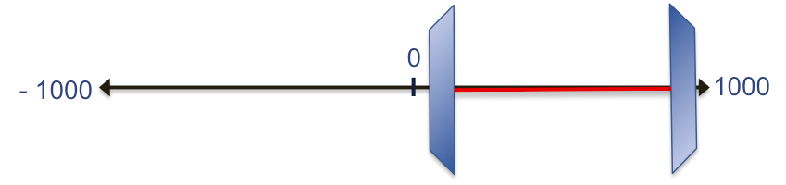

**Table 1: The minimum metabolic maintenance requirement for neurons.** This is a coarse-grained approximation of neuronal lipid, amino acid, and nucleic acid maintenance requirements converted into $\mu mol/gDW/hr$.  **cardiolipin is also known as diphosphatidylglycerol 

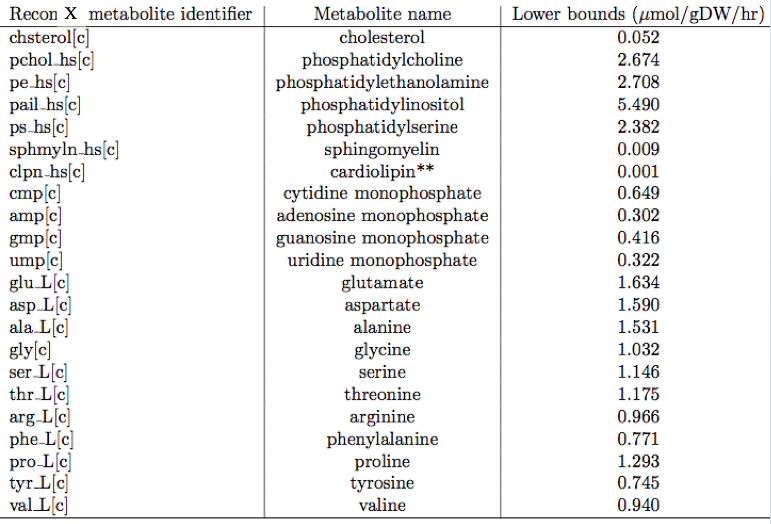

## A. Single pre-existing irreversible degradation reaction

In cases where only a single irreversible degradation reaction exists for a biomass maintenance precursor, the imposition of the constraint is straightforward. For example, the major cholesterol excretion pathway in the brain involves the hydroxylation of cholesterol into the oxysterol 24-hydroxycholesterol. Only a subset of neurons express this 24-hydroxylase enzyme ([HMR_1735](http://vmh.uni.lu/#human/all/HMR_1735)) and it is mainly found in dendrites and somata, rather than in axons or presynaptic terminals (reviewed in [5]). 

Therefore, add a lower bound ($v_1$, calculated above) on HMR_1735 (Table 1). 

modelConstrained = changeRxnBounds(modelConstrained, 'HMR_1735', v1, 'l');

## B. Single degradation reaction does not exist biochemically

A degradation reaction might not exist for a given biomass maintenance precursor. For example, the phospholipid cardiolipin is mainly present in the inner mitochondrial membrane, where it regulates the stability of the mitochondrial membrane protein complexes [6]. As part of mitochondria, cardiolipin reaches the lysosome during macroautophagy (reviewed in [7]). It is then degraded to form the negatively charged bis(monoacylglycero)phosphate (BMP) on internal membranes.  

Unless the corresponding demand reaction already exists in the model, a demand reaction can be added. 

modelConstrained = addDemandReaction(modelConstrained, 'clpn_hs[c]'); 

DM_clpn_hs[c]	clpn_hs[c] 	->	


Now, the constraint for cardiolipin (Table 1) can be imposed on the corresponding demand reaction

modelConstrained = changeRxnBounds(modelConstrained, 'DM_clpn_hs[c]', 0.001, 'l');

## C. Single reversible degradation reaction

In cases where the biomass precursor degradation reaction is reversible, it first needs to be split into two irreversible reactions. Thereafter, 'RXN_b' and 'RXN_f' represent the split backward and forward reactions, respectively. 

**i. Split the reversible reactions into irreversible**

Select a set of reversible degradation reactions 

sRxns = {'ASPTA'; 'GHMT2r'};

Copy the original model, except split a specific list of reversible degradation reactions into irreversible. 

Split sRxns into irreversible reactions

[modelIrrev] = convertToIrreversible(modelConstrained,'sRxns',sRxns);

Double check the indices of the reactions

for j=1:length(sRxns)
    if isempty(findRxnIDs(modelIrrev, [sRxns{j} '_f']))
        error('Forward reaction not found')
    end
    if isempty(findRxnIDs(modelIrrev, [sRxns{j} '_b']))
        error('Reverse reaction not found')
    end
end

**ii. Impose the calculated constraints**

Examples are given for aspartate and glutamate (Table 1)

constraints = [1.590; 1.146];

Identify the new reaction names

rxns = setdiff(modelIrrev.rxns, modelConstrained.rxns);

Using this list (rxns), manually identify the corresponding reactions that should be constrained

splitRxns= {'ASPTA_f'; 'GHMT2r_f'};

 Identify the indices of these split reactions in the new model

ind = findRxnIDs(modelIrrev, splitRxns);

Now, impose the constraints using a for loop. To account for experimental errors, define the percentage of error on the calculated constraint. Here 25% was used on the lower bound.

expError = 0.25;
modelConstrained = modelIrrev;
for i = 1:length(splitRxns);
    modelConstrained = changeRxnBounds(modelConstrained, splitRxns{i,1},...
        constraints(i,1)-constraints(i,1)*expError, 'l');
end

## D. Multiple irreversible degradation reactions

From the experimental literature, we know that several degradation pathways may be available for one biomass precursor in the specific organ. For example, in the brain, phosphatidylcholine (PC) can be degraded by 3 different metabolic pathways [8]:

- [PCHOLP_hs](http://vmh.uni.lu/#reaction/PCHOLP_hs): Phospholipase D acts on the choline/phosphate bond of PC to form choline and phosphatidic acid.

- [PLA2_2](http://vmh.uni.lu/#reaction/PLA2_2): Phospholipase A2 acts on the bond between the fatty acid and the hydroxyl group of PC to form a fatty acid (e.g. arachidonic acid or docosahexaenoic acid) and lysophosphatidylcholine. 

- [SMS](http://vmh.uni.lu/#reaction/SMS): Ceramide and PC can also be converted to sphingomyelin by sphingomyelin synthetase. 

Define the set of reactions that will represent degradation 

multipleRxnList={'PCHOLP_hs', 'PLA2_2', 'SMS'};

Make sure that all the reactions are irreversible. The lower bounds should be 0 and the upper bounds 1000.  

modelConstrained.lb(findRxnIDs(model, multipleRxnList));

ans =

     0

     0

     0

modelConstrained.ub(findRxnIDs(model, multipleRxnList));

ans =

        1000

        1000

        1000

Generate and add the constraints. Please see Table 1 for an example of the constraint to be set for the degradation of PC (2.674 $\mu mol/gDW/hr$)

rxnInd = findRxnIDs(modelConstrained, multipleRxnList);
c=[1,1,1];
d=2.674; 
ineqSense='G';
modelConstrainedAb=constrainRxnListAboveBound(modelConstrained,multipleRxnList,c,d,ineqSense);

Check the constraints are there

[nMet,nRxn]=size(modelConstrainedAb.S);
modelConstrainedAb

modelConstrainedAb =                rxns: {10604×1 cell}
               mets: {5835×1 cell}
           metNames: {5835×1 cell}
        metFormulas: {5835×1 cell}
                 lb: [10604×1 double]
                 ub: [10604×1 double]
         subSystems: {10604×1 cell}
           rxnNames: {10604×1 cell}
      rxnReferences: {10604×1 cell}
       rxnECNumbers: {10604×1 cell}
           rxnNotes: {10604×1 cell}
                  S: [5835×10604 double]
                  b: [5835×1 double]
                  c: [10604×1 double]
              genes: {1145×1 cell}
            grRules: {10604×1 cell}
          metCharge: [5835×1 double]
         rxnGeneMat: [10604×1145 logical]
              rules: {10604×1 cell}
     biomassRxnAbbr: 'biomass'
           Elements: {'H'  'C'  'O'  'P'  'S'  'N'  'Mg'  'X'  'Fe'  'Zn'  'Co'  'R'  'Ca'  'Y'  'I'  'Na'  'Cl'  'K'  'R'  'FULLR'}
            modelID: 'ReconX'
             csense: [5836×1 char]
              match: [10604×1 double]
    reversibl

Solve the FBA problem with added constraints C*v >= d , with or without objective function

%modelConstrainedAb = changeObjective(modelConstrainedAb, 'DM_atp_c_');
FBAsolution = optimizeCbModel(modelConstrainedAb,'max',1e-6);

Check the values of the added fluxes

FBAsolution.x(rxnInd)

ans =     1.0746
    0.5313
    1.0681

Should be greater than the value of d

sum(c*FBAsolution.x(rxnInd))

ans = 2.6740

return;

## TIMING

The most time consuming step when imposing constraints, is the initial collection of information required. Depending on the available experimental literature, it can take between 4-8 weeks to retrieve the biomass composition and the turnover rates of the different biomass precursors. It is indispensable to correctly convert the obtained data into the corresponding fluxes. If dry weight is being used, it is also necessary to know the water composition of the specific cell-type or organ. Once all the constraints are available, it can take less than 5 minutes to impose the constraints on the corresponding reaction bounds, according to the information provided in this tutorial. 

## ANTICIPATED RESULTS

After imposing the above constraints, we can now test the likely outcome of an optimisation problem using a constraint-based model. For example, we can take advantage of sparseFBA to identify the minimal set of essential reactions required to fulfill a certain objective function (e.g. [DM_atp_c_](http://vmh.uni.lu/#reaction/DM_atp_c_)).

originalTest = model; 
originalTest = changeObjective(originalTest , 'DM_atp_c_');
[vSparseOriginal, sparseRxnBoolOriginal, essentialRxnBoolOriginal]  = sparseFBA(originalTest);

In the absence of constraints, the minimal set of reactions required to maximise the objective function is 15 essential reactions.

constrainedTest = modelConstrainedAb; 
constrainedTest = changeObjective(constrainedTest, 'DM_atp_c_');
[vSparseConstrained, sparseRxnBoolConstrained, essentialRxnBoolConstrained]  = sparseFBA(constrainedTest);

After the addition of constraints, the minimal set of reactions required is increased to 47 essential reactions. Therefore, it is useful to integrate cell-type specific constraints in order to restrict the solution space.

## REFERENCES

1. Thiele, I.  and Palsson B.Ø. A protocol for generating a high-quality genome-scale metabolic reconstruction. Nat. Protocols. 5(1), 93–121(2010).

2. Feist, A.M. and Palsson, B.Ø. The biomass objective function. Current Opinion in Microbiology. 13(3), 344–349 (2010).  

3. Kuhar, M.J. On the use of protein turnover and half-lives. Neuropsychopharmacology. 34(5), 1172–1173 (2008). 

4. Sokoloff, L. et al. The [14C]deoxyglucose method for the measurement of local cerebral  glucose utilization: theory, procedure, and normal values in the  conscious and anesthetized albino rat. J Neurochem. 28(5):897-916 (1977).

5. Zhang, J. and Liu, Q. Cholesterol metabolism and homeostasis in the brain. Protein Cell. 6(4), 254-64 (2015). 

6. Martinez-Vicente, M. Neuronal mitophagy in neurodegenerative diseases. Front. Mol. Neurosci. 8, 10:64 (2017).

7. Schulze, H. et al. Principles of lysosomal membrane degradation: cellular topology and biochemistry of lysosomal lipid degradation. Biochim. Biophys. Acta. 1793(4), 674-83 (2009). 

8. Lajtha, A. and Sylvester, V. Handbook of Neurochemistry and Molecular Neurobiology. Springer; 2008. Available [here](http://www.springer.com/de/book/9780387303512). 